# Suspension: system modeling

## System modeling

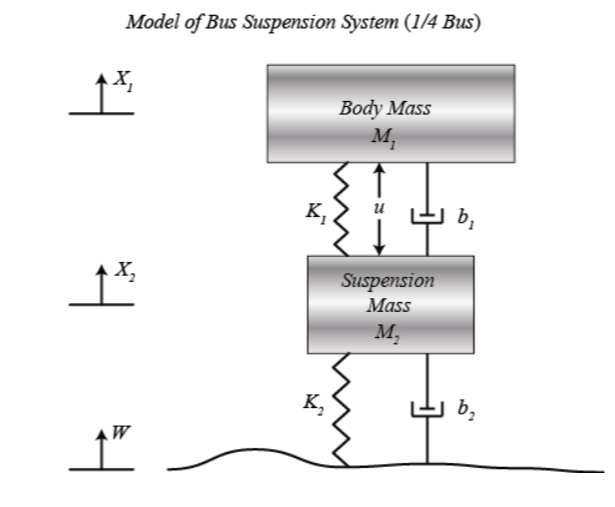

## Differential equation

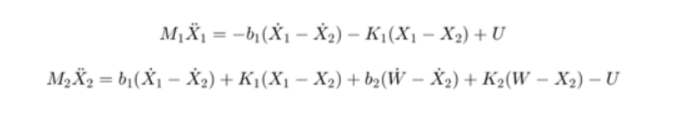

## State Space equation

The specific derivation from the above equations to the transfer functions G1(s) and G2(s) is shown below where each transfer function has an output of, X1-X2, and inputs of U and W, respectively.

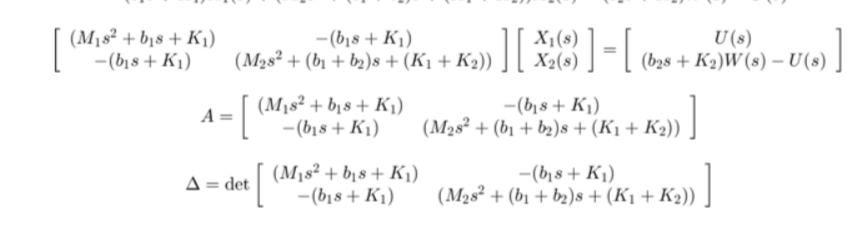

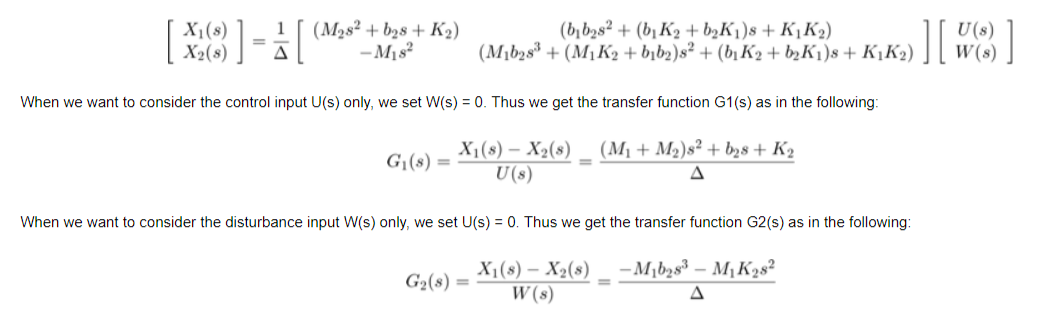

## Code

M1 = 2500;
M2 = 320;
K1 = 80000;
K2 = 500000;
b1 = 350;
b2 = 15020;

s = tf('s');
G1 = ((M1+M2)*s^2+b2*s+K2)/((M1*s^2+b1*s+K1)*(M2*s^2+(b1+b2)*s+(K1+K2))-(b1*s+K1)*(b1*s+K1));
G2 = (-M1*b2*s^3-M1*K2*s^2)/((M1*s^2+b1*s+K1)*(M2*s^2+(b1+b2)*s+(K1+K2))-(b1*s+K1)*(b1*s+K1));